# Laboratorium problemowe 2 - stanowisko wahadła rekacyjnego

## Sprawozdanie z zajęć nr 4

## Dawid Lisek

## Paweł Mańka

## Pon. 8.00 23.10.2023

% time = [0, 3, 5, 7, 10, 13, 16, 19, 22]
% amp = [0, 0.2, 0.4, 0.6, 0.3, -0.3, -0.3, 0.2, -0.3]

time = [0, 3, 6, 9, 12, 15, 18, 21, 24];
amp = [0, 0.3, -0.3, 0.5, -0.5, 0.6, -0.6, 0.7, -0.7];

Na zajęciac z pomocą multimetra zostalo zmierzone napiecie przy wysokich wartosciach sterowania. 

Widac na wykresie ze silnik po jakims czasie wylacza sie (ma przerwy w przeplywie pradu) co skutkuje niedokladnym

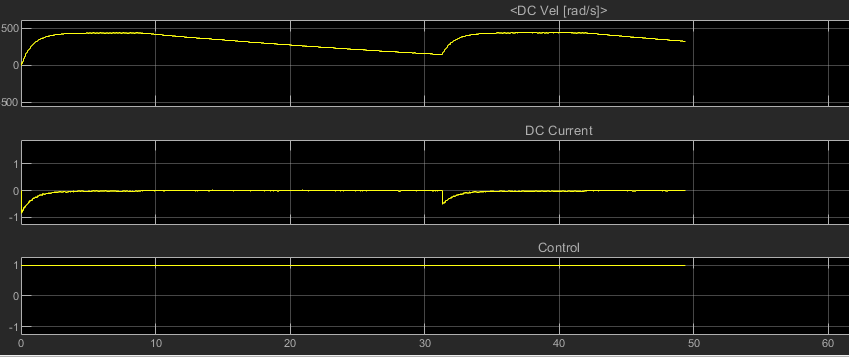

Zauważono rowniez roznice wzgledem multimetra a napiecia (funkcja napiecia od sterowania nie jest lniowa) dlatego zrobiona zostala tabelka napiecia od sterowania pwm

voltage = [-11.71, -10.69, -9.51, -8.32, -7.13, -5.93, -4.74, -3.55, -2.36, -1.18, 0, 1.61, 2.33, 3.53, 4.69, 5.91, 7.10, 8.27, 9.47, 10.66, 11.75];
u = -1:0.1:1;
Sterowanie = transpose(u);
Napiecie = transpose(voltage);

Tabelka:

T = table(Sterowanie, Napiecie)

T = 21×2 table
    Sterowanie    Napiecie
    __________    ________

         -1        -11.71 
       -0.9        -10.69 
       -0.8         -9.51 
       -0.7         -8.32 
       -0.6         -7.13 
       -0.5         -5.93 
       -0.4         -4.74 
       -0.3         -3.55 
       -0.2         -2.36 
       -0.1         -1.18 
          0             0 
        0.1          1.61 
        0.2          2.33 
        0.3          3.53 
        0.4          4.69 
        0.5          5.91 


Następnie zostal sprawdzony sygnal schodkowy dla duzych wartosci i dziala 

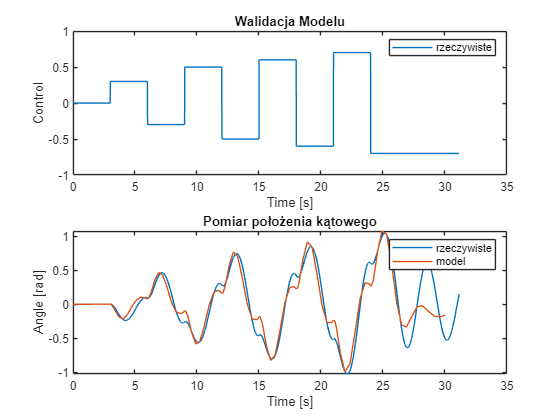

model_rzeczywisty = sygnal_schodkowy_nr1;
signal_model_real = sygnal_schodkowy_nr1.signals;
% model_rzeczywisty = walidacja_modelu_nr5;
% signal_model_real = walidacja_modelu_nr5.signals;
% sim("src\simulink_models\model_walidacyjny\model_matematyczny_2018a.slx");

model_matematyczny = out.model_matematyczny_nr1;
signal_model_mat = model_matematyczny.signals;

figure;
subplot(2, 1, 1)
plot(model_rzeczywisty.time, signal_model_real(8).values)
xlabel('Time [s]')
legend('rzeczywiste')
ylabel('Control')
title('Walidacja Modelu')

subplot(2, 1, 2)
plot(model_rzeczywisty.time, signal_model_real(1).values)
hold on;
val = reshape(signal_model_mat(1).values, 1, []);
plot(model_matematyczny.time, val)
hold off;
legend('rzeczywiste', 'model')
xlabel('Time [s]')
ylabel('Angle [rad]')
title('Pomiar położenia kątowego')

figure;
subplot(2, 1, 1)
plot(model_rzeczywisty.time, signal_model_real(8).values)
xlabel('Time [s]')
legend('rzeczywiste', 'model')

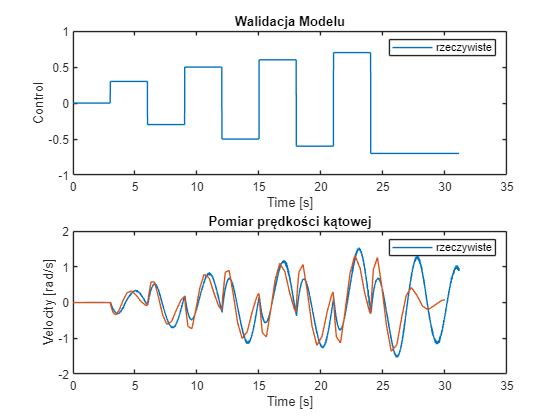

ylabel('Control')
title('Walidacja Modelu')

subplot(2, 1, 2)
plot(model_rzeczywisty.time, signal_model_real(4).values)
hold on;
val = reshape(signal_model_mat(2).values, 1, []);
plot(model_matematyczny.time, val)
hold off;
xlabel('Time [s]')
legend('rzeczywiste')
ylabel('Velocity [rad/s]')
title('Pomiar prędkości kątowej')

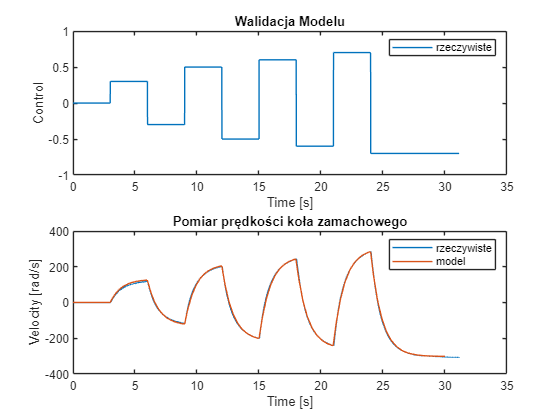

figure;
subplot(2, 1, 1)
plot(model_rzeczywisty.time, signal_model_real(8).values)
xlabel('Time [s]')
legend('rzeczywiste')
ylabel('Control')
title('Walidacja Modelu')

subplot(2, 1, 2)
plot(model_rzeczywisty.time, signal_model_real(6).values)
hold on;
val = reshape(signal_model_mat(3).values, 1, []);
plot(model_matematyczny.time, val)
hold off;
xlabel('Time [s]')
legend('rzeczywiste', 'model')
ylabel('Velocity [rad/s]')
title('Pomiar prędkości koła zamachowego')

Następnie sprawdziliśmy male sterowania -0.1, 0, 0.1 

model_rzeczywisty = sygnal_schodkowy_nr2;

 Wartośc napięcia zmierzona na silniku w zależności od sterowania:

voltage = [-11.71, -10.69, -9.51, -8.32, -7.13, -5.93, -4.74, -3.55, -2.36, -1.18, 0, 1.61, 2.33, 3.53, 4.69, 5.91, 7.10, 8.27, 9.47, 10.66, 11.75]

voltage =   -11.7100  -10.6900   -9.5100   -8.3200   -7.1300   -5.9300   -4.7400   -3.5500   -2.3600   -1.1800         0    1.6100    2.3300    3.5300    4.6900    5.9100    7.1000    8.2700    9.4700   10.6600   11.7500


u = -1:0.1:1

u =    -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


p_volt = polyfit(u, voltage, 1)

p_volt =    11.8238    0.0095


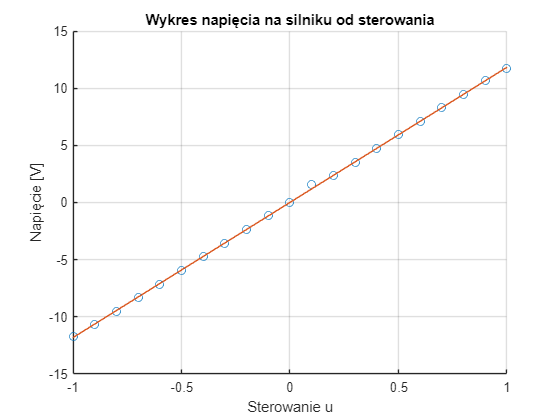

figure
hold on
plot(u, voltage, 'o')
plot(u, polyval(p_volt, u))
hold off
grid on
title('Wykres napięcia na silniku od sterowania')
xlabel('Sterowanie u')
ylabel('Napięcie [V]')

Następnie przy pomocy narzędzie model linearizer został wyznaczony punkt równowagi w dolnym położeniu wahadła. Wyznaczona została macierz stanu oraz sterowalności. Na podstawie macierzy stanu oraz macierzy wejść obliczone zostały wzmocnienia dla regulatora LQR, który będzie testowany na następnych zajęciach oraz dostrajany.

linsys1.A

ans =          0    1.0000         0
   -4.9764   -1.1417    0.0145
         0         0   -1.1309


linsys1.B

ans =          0
   -5.2369
  488.6480


linsys1.C

ans =      1     0     0
     0     1     0
     0     0     1


linsys1.D

ans =      0
     0
     0


co = ctrb(linsys1.A, linsys1.B)

co =          0   -5.2369   13.0867
   -5.2369   13.0867    3.0816
  488.6480 -552.6005  624.9228


rank(co)

ans = 3

K = lqr(linsys1.a, linsys1.b, eye(3), 1)

K =    -0.0278   -0.0041    0.9977
